I=0:0.05:0.8;
T=10000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_

dir_modelo = "SEIRS_Test.slx";
data_S=[];
data_E=[];
data_I=[];
data_R=[];
for i=I
    u=i;
    prueba_sim=sim(dir_modelo);
    data_S=[data_S,prueba_sim.S.signals.values(end)];
    data_E=[data_E,prueba_sim.E.signals.values(end)];
    data_I=[data_I,prueba_sim.I.signals.values(end)];
    data_R=[data_R,prueba_sim.R.signals.values(end)];
end

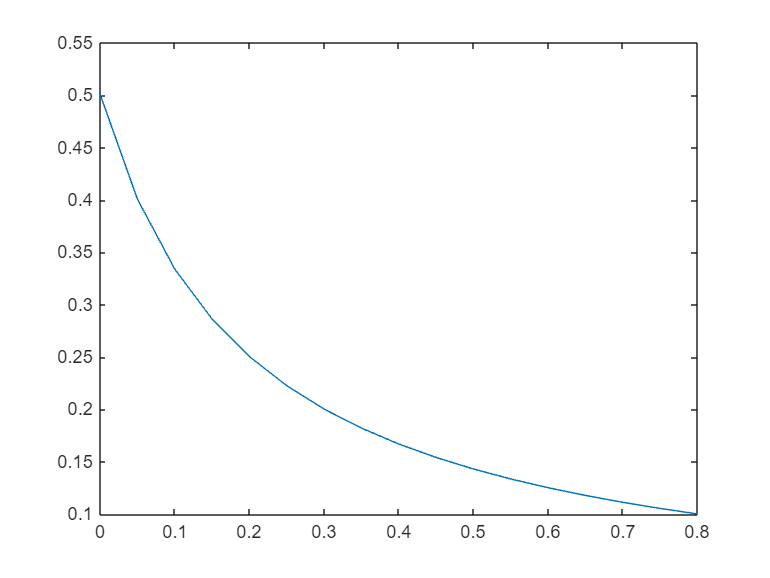


plot(I,data_S)

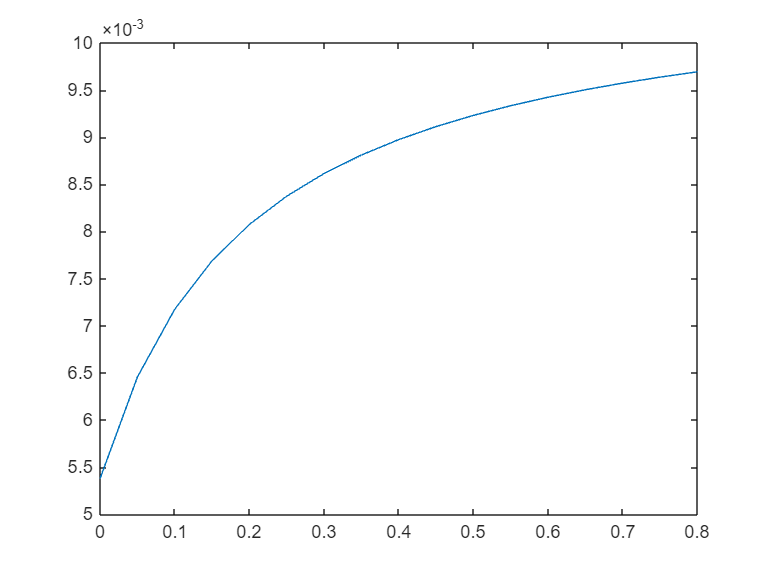

plot(I,data_E)

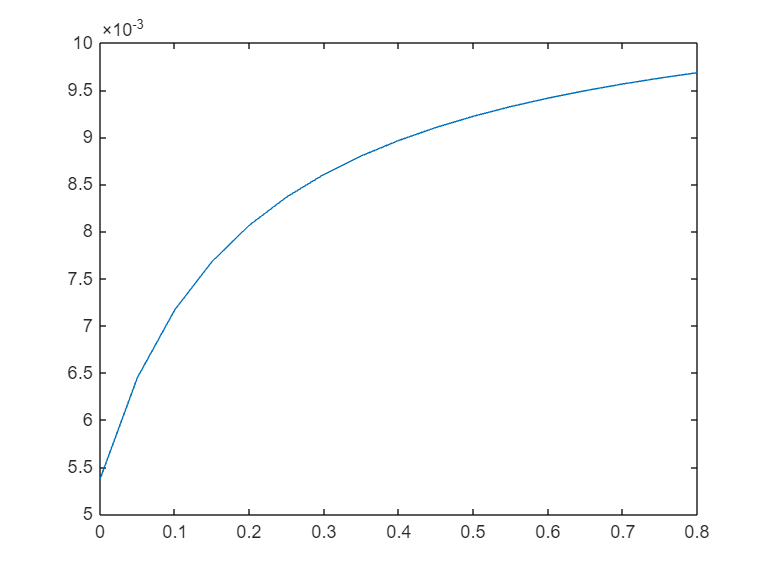

plot(I,data_I)

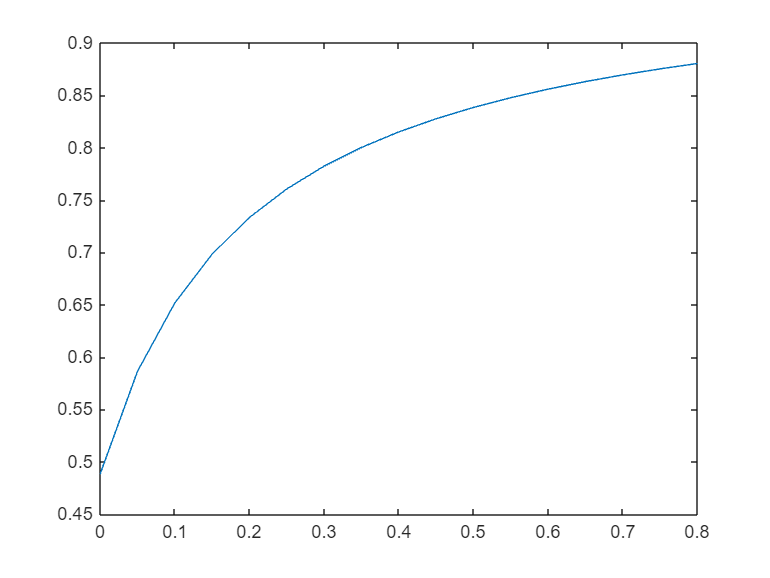

plot(I,data_R)


I=0:0.1:0.8;
T=10000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_

dir_modelo = "SEIRS_Test.slx";
data=[];
for i=I
    u=i;
    prueba_sim=sim(dir_modelo);
    data=[data,prueba_sim];
end

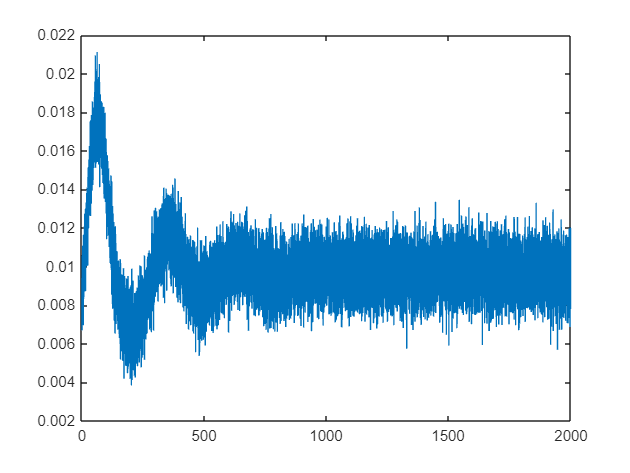

idx=9;
plot(data(idx).I.time,data(idx).I.signals.values)

### Toma de datos

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
Rango_PRBS=[0.5 0.7];
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data=sim(dir_modelo);

Y=Sim_Data.I.signals.values;
U=Sim_Data.Entrada_U.signals.values;
t=Sim_Data.I.time;
save("Y_3","Y")
save("U_3","U")
save("t_3","t")

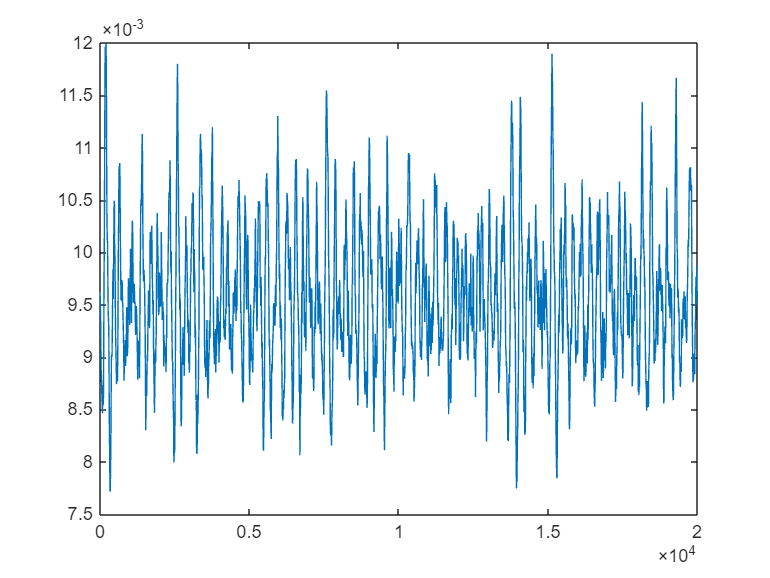

plot(Sim_Data.I.time,Sim_Data.I.signals.values)

% Definir el vector de tiempo (en Dias)
t = 0:10:T;  % T Dias, con un paso de 10 Dias

% Definir la señal de entrada sinusoidal
%u_sin = -sin(t * 2 * pi / 365) * 0.2;  % Señal sinusoidal con amplitud 0.2
u=ones(2001,1)*0.1;

y_sim = lsim(bj42441, u);

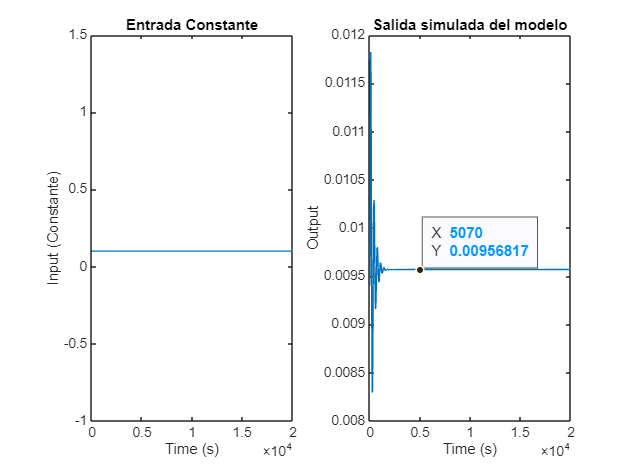


% Graficar la entrada y la salida simulada
subplot(1,2,1)
plot(t, u);
xlabel('Time (s)');
ylabel('Input (Constante)');
title('Entrada Constante');

y_sim_lin=y_sim+0.0094;
subplot(1,2,2)
plot(t, y_sim_lin);
xlabel('Time (s)');
ylabel('Output');
title('Salida simulada del modelo');